# Plot by Source

Description: This algorithm plot  bar and box of mean and weighted mean capacity factor. Also, it plots the share of electricity genreation by region for the specific source.

Also it makes a table at the end to summarize the data.

Developed by Natanael Bolson

Supervised by Prof. Tad Patzek 

Energy Geosystems Group -ANPERC - KAUST 11/2020

clc
clear 
close all
run CF_Calculation.mlx

## Color


Color=[178,24,43        % Africa
       214,96,77        % Asia
       90,174,97        % CIS
       27,120,55        % Europe
       146,197,222      % Latin America
       33,102,172       % MENA
       128,115,172      % North America
       84,39,136        % Oceania
       55,55,55]/255;   % World      

ColorB=flipud(Color);% For the boxplot


## Legends

% Bar Plots
legWB={'$$\mathrm{Africa}$$';'$$\mathrm{Asia}$$';'$$\mathrm{CIS}$$';...
    '$$\mathrm{Eur.}$$';'$$\mathrm{L.Am.}$$';'$$\mathrm{MENA}$$';...
    '$$\mathrm{N.Am.}$$';'$$\mathrm{Oce.}$$';'$$\mathrm{World}$$';};
% Without World
leg={'$$\mathrm{Africa}$$';'$$\mathrm{Asia}$$';'$$\mathrm{CIS}$$';...
    '$$\mathrm{Europe}$$';'$$\mathrm{Latin~Am.}$$';'$$\mathrm{MENA}$$';...
    '$$\mathrm{North~Am.}$$';'$$\mathrm{Oceania}$$';};


## Biomass

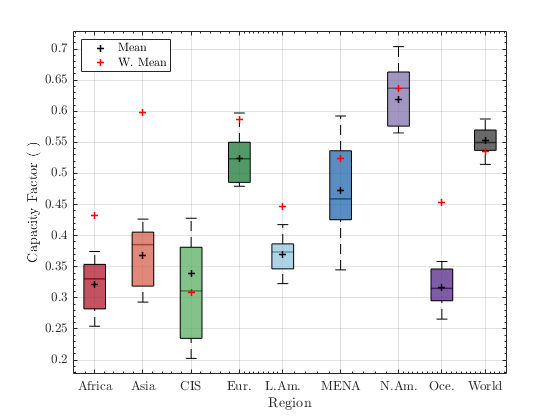


X=categorical(legWB);
x=[1 2 3 4 4.9 6.1 7.3 8.2 9.1];
figure('Name','Box Bio')
hold on
plot(x,Mean_CF_Bio,'+k','LineWidth',1.5)
plot(x,Mean_CF_W_Bio,'+r','LineWidth',1.5)
boxplot(Mat_CF_Bio,'position',x,'symbol','');%,'Whi+ker',0

h = findobj(gca,'Tag','Box');
for j=1:length(h) 
patch(get(h(j),'XData'),get(h(j),'YData'),ColorB(j,:),'FaceAlpha',.75);
end 
lines = findobj(gcf, 'type', 'line', 'Tag', 'Median');
set(lines, 'Color', 'k','LineWidth',1.5);
O = findobj(gcf,'tag','Outliers');
set(O,'MarkerSize',8,'LineWidth',1.5)
plot(x,Mean_CF_Bio,'+k','LineWidth',1.5)
plot(x,Mean_CF_W_Bio,'+r','LineWidth',1.5)
xlabel('$$\mathrm{Region}$$','interpreter','latex')
ylabel('$$\mathrm{Capacity~Factor~(~)}$$','interpreter','latex')
legend({'Mean','W.~Mean'},'Location','northwest','FontSize', 12,'NumColumns',1,...
    'box','on','interpreter','latex')
xticks(x)
set(gca, 'XTickLabel', X,'Fontsize',14);
box on
grid on
xtickangle(0)
set(gca,'XMinorTick','on','YMinorTick','on')
 set(gca,'Fontsize',13,'TickDir','in','FontWeight','normal','GridAlpha',0.13,...
     'LineWidth',0.2,'TickLength',[0.01 0.01],'TickLabelInterpreter','latex') 
% print('-dpdf','-r400','Biomass_CF_B.pdf');
print('-dpng','-r400','Biomass_CF_B.png');

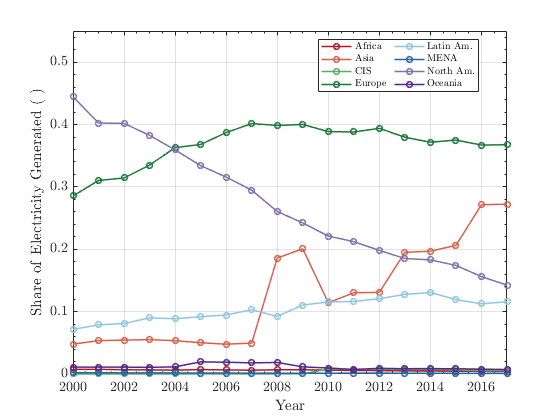


figure('Name','Share Bio Electricity')
plot(Year,Africa_El_Bio,'-o','Color',Color(1,:),'linewidth',1.5)
hold on
plot(Year,Asia_El_Bio,'-o','Color',Color(2,:),'linewidth',1.5)
plot(Year,CIS_El_Bio,'-o','Color',Color(3,:),'linewidth',1.5)
plot(Year,Europe_El_Bio,'-o','Color',Color(4,:),'linewidth',1.5)
plot(Year,LatAm_El_Bio,'-o','Color',Color(5,:),'linewidth',1.5)
plot(Year,MENA_El_Bio,'-o','Color',Color(6,:),'linewidth',1.5)
plot(Year,NorAm_El_Bio,'-o','Color',Color(7,:),'linewidth',1.5)
plot(Year,Oceania_El_Bio,'-o','Color',Color(8,:),'linewidth',1.5)
legend(leg,'Location','best','FontSize', 10,'NumColumns',2,...
    'interpreter','latex')
xlim([2000 2017])
ylim([0 0.55])
xlabel('$$\mathrm{Year}$$','interpreter','latex')
ylabel('$$\mathrm{Share~of~Electricity~Generated~(~)}$$','interpreter','latex')
box on
grid on
set(gca,'XMinorTick','on','YMinorTick','on')
set(gca,'Fontsize',14,'TickDir','in','FontWeight','normal','GridAlpha',0.13,...
     'LineWidth',0.2,'TickLength',[0.01 0.01],'TickLabelInterpreter','latex')
%  print('-depsc2','-r400','Biomass_Share.eps');
print('-dpng','-r400','Biomass_Share.png');

## Fossil

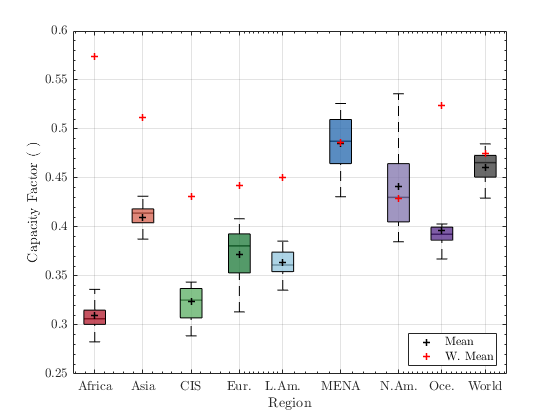

% Figures

 
X=categorical(legWB);

figure('Name','Box Fos')
hold on
plot(x,Mean_CF_Fos,'+k','LineWidth',1.5)
plot(x,Mean_CF_W_Fos,'+r','LineWidth',1.5)
boxplot(Mat_CF_Fos,'position',x,'symbol','');

h = findobj(gca,'Tag','Box');
for j=1:length(h) 
patch(get(h(j),'XData'),get(h(j),'YData'),ColorB(j,:),'FaceAlpha',.75);
end 
lines = findobj(gcf, 'type', 'line', 'Tag', 'Median');
set(lines, 'Color', 'k','LineWidth',1.5);
O = findobj(gcf,'tag','Outliers');
set(O,'MarkerSize',8,'LineWidth',1.5)
plot(x,Mean_CF_Fos,'+k','LineWidth',1.5)
plot(x,Mean_CF_W_Fos,'+r','LineWidth',1.5)
xlabel('$$\mathrm{Region}$$','interpreter','latex')
ylabel('$$\mathrm{Capacity~Factor~(~)}$$','interpreter','latex')
legend({'Mean','W.~Mean'},'Location','best','FontSize', 12,'NumColumns',1,...
    'box','on','interpreter','latex')
xticks(x)
set(gca, 'XTickLabel', X);
ylim([0.25 0.6])
box on
grid on
xtickangle(0)
set(gca,'XMinorTick','on','YMinorTick','on')
 set(gca,'Fontsize',13,'TickDir','in','FontWeight','normal','GridAlpha',0.13,...
     'LineWidth',0.2,'TickLength',[0.01 0.01],'TickLabelInterpreter','latex') 
% print('-dpdf','-r400','Fossil_CF_B.pdf');
print('-dpng','-r400','Fossil_CF_B.png');

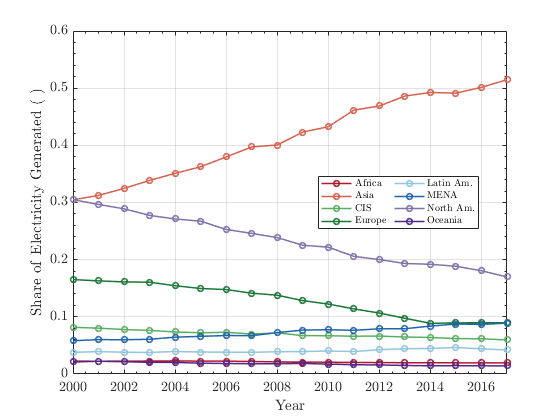

 
figure('Name','Share Fos Electricity')
plot(Year,Africa_El_Fos,'-o','Color',Color(1,:),'linewidth',1.5)
hold on
plot(Year,Asia_El_Fos,'-o','Color',Color(2,:),'linewidth',1.5)
plot(Year,CIS_El_Fos,'-o','Color',Color(3,:),'linewidth',1.5)
plot(Year,Europe_El_Fos,'-o','Color',Color(4,:),'linewidth',1.5)
plot(Year,LatAm_El_Fos,'-o','Color',Color(5,:),'linewidth',1.5)
plot(Year,MENA_El_Fos,'-o','Color',Color(6,:),'linewidth',1.5)
plot(Year,NorAm_El_Fos,'-o','Color',Color(7,:),'linewidth',1.5)
plot(Year,Oceania_El_Fos,'-o','Color',Color(8,:),'linewidth',1.5)
legend(leg,'Location','best','FontSize', 10,'NumColumns',2,...
    'interpreter','latex')
xlabel('$$\mathrm{Year}$$','interpreter','latex')
% ylabel('$$\mathrm{Electricity~from~Fossil~(~)}$$','interpreter','latex')
ylabel('$$\mathrm{Share~of~Electricity~Generated~(~)}$$','interpreter','latex')
xlim([2000 2017])
box on
grid on
set(gca,'XMinorTick','on','YMinorTick','on')
set(gca,'Fontsize',14,'TickDir','in','FontWeight','normal','GridAlpha',0.13,...
     'LineWidth',0.2,'TickLength',[0.01 0.01],'TickLabelInterpreter','latex')
% print('-depsc2','-r400','Fossil_Share.eps');
print('-dpng','-r400','Fossil_Share.png');

## Geothermal

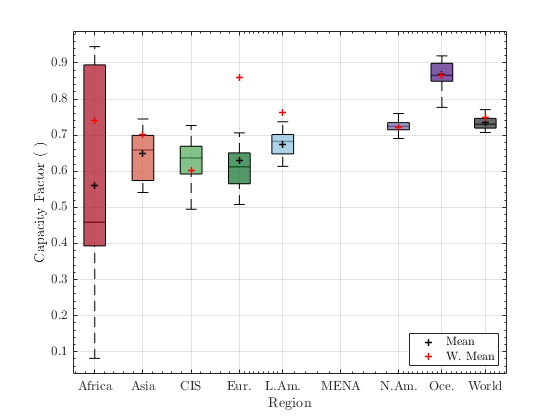


 
X=categorical(legWB);

figure('Name','Box Geo')
hold on
plot(x,Mean_CF_Geo,'+k','LineWidth',1.5)
plot(x,Mean_CF_W_Geo,'+r','LineWidth',1.5)
boxplot(Mat_CF_Geo,'position',x,'symbol','');
h = findobj(gca,'Tag','Box');
for j=1:length(h) 
patch(get(h(j),'XData'),get(h(j),'YData'),ColorB(j,:),'FaceAlpha',.75);
end 
lines = findobj(gcf, 'type', 'line', 'Tag', 'Median');
set(lines, 'Color', 'k','LineWidth',1.5);
O = findobj(gcf,'tag','Outliers');
set(O,'MarkerSize',8,'LineWidth',1.5)
plot(x,Mean_CF_Geo,'+k','LineWidth',1.5)
plot(x,Mean_CF_W_Geo,'+r','LineWidth',1.5)
xlabel('$$\mathrm{Region}$$','interpreter','latex')
ylabel('$$\mathrm{Capacity~Factor~(~)}$$','interpreter','latex')
legend({'Mean','W.~Mean'},'Location','southeast','FontSize', 12,'NumColumns',1,...
    'box','on','interpreter','latex')
set(gca, 'XTickLabel', X);
box on
grid on
xtickangle(0)
set(gca,'XMinorTick','on','YMinorTick','on')
 set(gca,'Fontsize',13,'TickDir','in','FontWeight','normal','GridAlpha',0.13,...
     'LineWidth',0.2,'TickLength',[0.01 0.01],'TickLabelInterpreter','latex') 
% print('-dpdf','-r400','Geothermal_CF_B.pdf');
print('-dpng','-r400','Geothermal_CF_B.png');

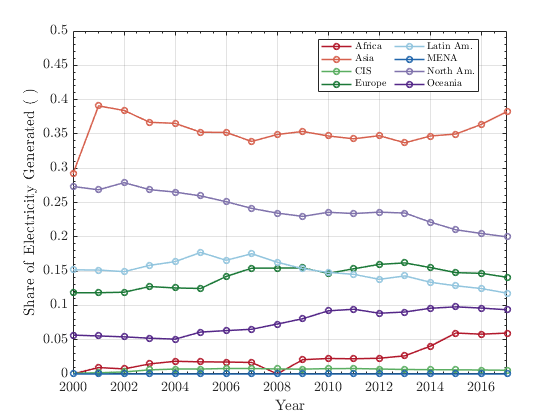

 
figure('Name','Share Geo Electricity')
plot(Year,Africa_El_Geo,'-o','Color',Color(1,:),'linewidth',1.5)
hold on
plot(Year,Asia_El_Geo,'-o','Color',Color(2,:),'linewidth',1.5)
plot(Year,CIS_El_Geo,'-o','Color',Color(3,:),'linewidth',1.5)
plot(Year,Europe_El_Geo,'-o','Color',Color(4,:),'linewidth',1.5)
plot(Year,LatAm_El_Geo,'-o','Color',Color(5,:),'linewidth',1.5)
plot(Year,MENA_El_Geo,'-o','Color',Color(6,:),'linewidth',1.5)
plot(Year,NorAm_El_Geo,'-o','Color',Color(7,:),'linewidth',1.5)
plot(Year,Oceania_El_Geo,'-o','Color',Color(8,:),'linewidth',1.5)
legend(leg,'Location','best','FontSize', 10,'NumColumns',2,...
    'interpreter','latex')
xlabel('$$\mathrm{Year}$$','interpreter','latex')
% ylabel('$$\mathrm{Electricity~from~Geothermal~(~)}$$','interpreter','latex')
ylabel('$$\mathrm{Share~of~Electricity~Generated~(~)}$$','interpreter','latex')
ylim([0 0.5])
xlim([2000 2017])
box on
grid on
set(gca,'XMinorTick','on','YMinorTick','on')
set(gca,'Fontsize',14,'TickDir','in','FontWeight','normal','GridAlpha',0.13,...
     'LineWidth',0.2,'TickLength',[0.01 0.01],'TickLabelInterpreter','latex')
% print('-depsc2','-r400','Geothermal_Share.eps');
print('-dpng','-r400','Geothermal_Share.png');

## Hydro

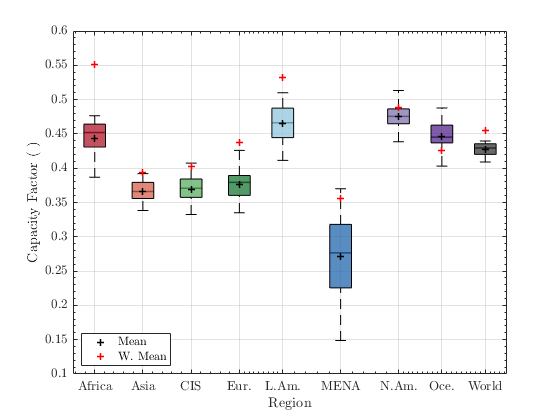



X=categorical(legWB);

figure('Name','Box Hyd')
hold on
plot(x,Mean_CF_Hyd,'+k','LineWidth',1.5)
plot(x,Mean_CF_W_Hyd,'+r','LineWidth',1.5)
boxplot(Mat_CF_Hyd,'position',x,'symbol','');

h = findobj(gca,'Tag','Box');
for j=1:length(h) 
patch(get(h(j),'XData'),get(h(j),'YData'),ColorB(j,:),'FaceAlpha',.75);
end 
lines = findobj(gcf, 'type', 'line', 'Tag', 'Median');
set(lines, 'Color', 'k','LineWidth',1.5);
O = findobj(gcf,'tag','Outliers');
set(O,'MarkerSize',8,'LineWidth',1.5)
plot(x,Mean_CF_Hyd,'+k','LineWidth',1.5)
plot(x,Mean_CF_W_Hyd,'+r','LineWidth',1.5)
xlabel('$$\mathrm{Region}$$','interpreter','latex')
ylabel('$$\mathrm{Capacity~Factor~(~)}$$','interpreter','latex')
legend({'Mean','W.~Mean'},'Location','southwest','FontSize', 12,'NumColumns',1,...
    'box','on','interpreter','latex')
set(gca, 'XTickLabel', X);
box on
grid on
xtickangle(0)
ylim([0.1 0.6])
set(gca,'XMinorTick','on','YMinorTick','on')
 set(gca,'Fontsize',13,'TickDir','in','FontWeight','normal','GridAlpha',0.13,...
     'LineWidth',0.2,'TickLength',[0.01 0.01],'TickLabelInterpreter','latex') 
% print('-dpdf','-r400','Hy+ro_CF_B.pdf');
print('-dpng','-r400','Hydro_CF_B.png');

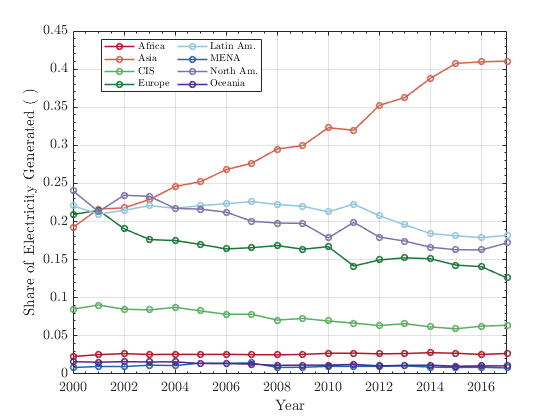

 
figure('Name','Share Hyd Electricity')
plot(Year,Africa_El_Hyd,'-o','Color',Color(1,:),'linewidth',1.5)
hold on
plot(Year,Asia_El_Hyd,'-o','Color',Color(2,:),'linewidth',1.5)
plot(Year,CIS_El_Hyd,'-o','Color',Color(3,:),'linewidth',1.5)
plot(Year,Europe_El_Hyd,'-o','Color',Color(4,:),'linewidth',1.5)
plot(Year,LatAm_El_Hyd,'-o','Color',Color(5,:),'linewidth',1.5)
plot(Year,MENA_El_Hyd,'-o','Color',Color(6,:),'linewidth',1.5)
plot(Year,NorAm_El_Hyd,'-o','Color',Color(7,:),'linewidth',1.5)
plot(Year,Oceania_El_Hyd,'-o','Color',Color(8,:),'linewidth',1.5)
legend(leg,'Location','best','FontSize', 10,'NumColumns',2,...
    'interpreter','latex')
xlabel('$$\mathrm{Year}$$','interpreter','latex')
% ylabel('$$\mathrm{Electricity~from~Hy+ro~(~)}$$','interpreter','latex')
ylabel('$$\mathrm{Share~of~Electricity~Generated~(~)}$$','interpreter','latex')
xlim([2000 2017])
box on
grid on
set(gca,'XMinorTick','on','YMinorTick','on')
set(gca,'Fontsize',14,'TickDir','in','FontWeight','normal','GridAlpha',0.13,...
     'LineWidth',0.2,'TickLength',[0.01 0.01],'TickLabelInterpreter','latex')
%  print('-depsc2','-r400','Hy+ro_Share.eps');
print('-dpng','-r400','Hydro_Share.png');

## Nuclear

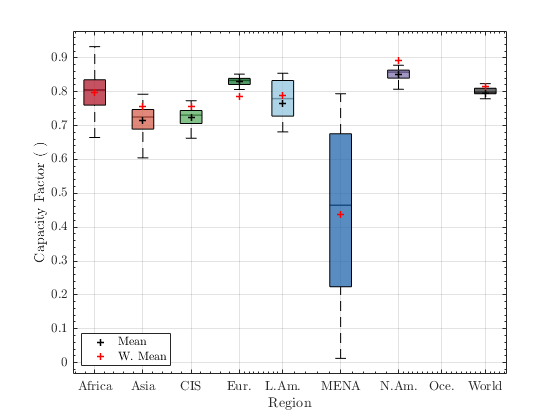


X=categorical(legWB);

figure('Name','Box Nuc')
hold on
plot(x,Mean_CF_Nuc,'+k','LineWidth',1.5)
plot(x,Mean_CF_W_Nuc,'+r','LineWidth',1.5)
boxplot(Mat_CF_Nuc,'position',x,'symbol','');

h = findobj(gca,'Tag','Box');
for j=1:length(h) 
patch(get(h(j),'XData'),get(h(j),'YData'),ColorB(j,:),'FaceAlpha',.75);
end 
lines = findobj(gcf, 'type', 'line', 'Tag', 'Median');
set(lines, 'Color', 'k','LineWidth',1.5);
O = findobj(gcf,'tag','Outliers');
set(O,'MarkerSize',8,'LineWidth',1.5)
plot(x,Mean_CF_Nuc,'+k','LineWidth',1.5)
plot(x,Mean_CF_W_Nuc,'+r','LineWidth',1.5)
xlabel('$$\mathrm{Region}$$','interpreter','latex')
ylabel('$$\mathrm{Capacity~Factor~(~)}$$','interpreter','latex')
legend({'Mean','W.~Mean'},'Location','southwest','FontSize', 12,'NumColumns',1,...
    'box','on','interpreter','latex')
set(gca, 'XTickLabel', X);
box on
grid on
xtickangle(0)
set(gca,'XMinorTick','on','YMinorTick','on')
 set(gca,'Fontsize',13,'TickDir','in','FontWeight','normal','GridAlpha',0.13,...
     'LineWidth',0.2,'TickLength',[0.01 0.01],'TickLabelInterpreter','latex') 
% print('-dpdf','-r400','Nuclear_CF_B.pdf');
print('-dpng','-r400','Nuclear_CF_B.png');

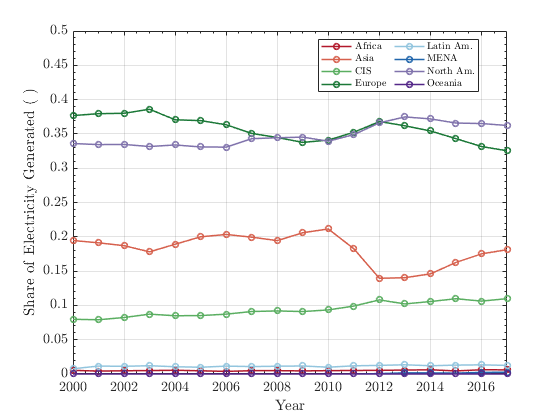

 
figure('Name','Share Nuc Electricity')
plot(Year,Africa_El_Nuc,'-o','Color',Color(1,:),'linewidth',1.5)
hold on
plot(Year,Asia_El_Nuc,'-o','Color',Color(2,:),'linewidth',1.5)
plot(Year,CIS_El_Nuc,'-o','Color',Color(3,:),'linewidth',1.5)
plot(Year,Europe_El_Nuc,'-o','Color',Color(4,:),'linewidth',1.5)
plot(Year,LatAm_El_Nuc,'-o','Color',Color(5,:),'linewidth',1.5)
plot(Year,MENA_El_Nuc,'-o','Color',Color(6,:),'linewidth',1.5)
plot(Year,NorAm_El_Nuc,'-o','Color',Color(7,:),'linewidth',1.5)
plot(Year,Oceania_El_Nuc,'-o','Color',Color(8,:),'linewidth',1.5)
legend(leg,'Location','best','FontSize', 10,'NumColumns',2,...
    'interpreter','latex')
xlabel('$$\mathrm{Year}$$','interpreter','latex')
% ylabel('$$\mathrm{Electricity~from~Nuclear~(~)}$$','interpreter','latex')
ylabel('$$\mathrm{Share~of~Electricity~Generated~(~)}$$','interpreter','latex')
ylim([0 0.5])
xlim([2000 2017])
box on
grid on
set(gca,'XMinorTick','on','YMinorTick','on')
set(gca,'Fontsize',14,'TickDir','in','FontWeight','normal','GridAlpha',0.13,...
     'LineWidth',0.2,'TickLength',[0.01 0.01],'TickLabelInterpreter','latex')
% print('-depsc2','-r400','Nuclear_Share.eps');
print('-dpng','-r400','Nuclear_Share.png');

## Solar

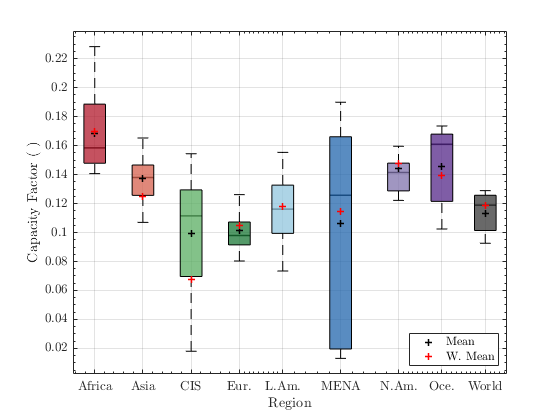


X=categorical(legWB);

figure('Name','Box Sol')
hold on
plot(x,Mean_CF_Sol,'+k','LineWidth',1.5)
plot(x,Mean_CF_W_Sol,'+r','LineWidth',1.5)
boxplot(Mat_CF_Sol,'position',x,'symbol','');

h = findobj(gca,'Tag','Box');
for j=1:length(h) 
patch(get(h(j),'XData'),get(h(j),'YData'),ColorB(j,:),'FaceAlpha',.75);
end 
lines = findobj(gcf, 'type', 'line', 'Tag', 'Median');
set(lines, 'Color', 'k','LineWidth',1.5);
O = findobj(gcf,'tag','Outliers');
set(O,'MarkerSize',8,'LineWidth',1.5)
plot(x,Mean_CF_Sol,'+k','LineWidth',1.5)
plot(x,Mean_CF_W_Sol,'+r','LineWidth',1.5)
xlabel('$$\mathrm{Region}$$','interpreter','latex')
ylabel('$$\mathrm{Capacity~Factor~(~)}$$','interpreter','latex')
legend({'Mean','W.~Mean'},'Location','SE','FontSize', 12,'NumColumns',1,...
    'box','on','interpreter','latex')
set(gca, 'XTickLabel', X);
box on
grid on
xtickangle(0)
set(gca,'XMinorTick','on','YMinorTick','on')
 set(gca,'Fontsize',13,'TickDir','in','FontWeight','normal','GridAlpha',0.13,...
     'LineWidth',0.2,'TickLength',[0.01 0.01],'TickLabelInterpreter','latex') 
% print('-dpdf','-r400','Solar_CF_B.pdf');
print('-dpng','-r400','Solar_CF_B.png');

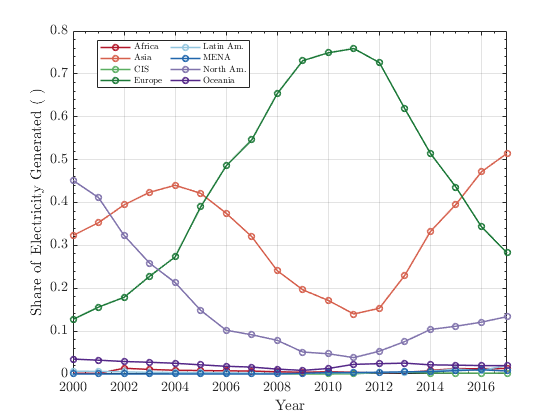

 
figure('Name','Share Sol Electricity')
plot(Year,Africa_El_Sol,'-o','Color',Color(1,:),'linewidth',1.5)
hold on
plot(Year,Asia_El_Sol,'-o','Color',Color(2,:),'linewidth',1.5)
plot(Year,CIS_El_Sol,'-o','Color',Color(3,:),'linewidth',1.5)
plot(Year,Europe_El_Sol,'-o','Color',Color(4,:),'linewidth',1.5)
plot(Year,LatAm_El_Sol,'-o','Color',Color(5,:),'linewidth',1.5)
plot(Year,MENA_El_Sol,'-o','Color',Color(6,:),'linewidth',1.5)
plot(Year,NorAm_El_Sol,'-o','Color',Color(7,:),'linewidth',1.5)
plot(Year,Oceania_El_Sol,'-o','Color',Color(8,:),'linewidth',1.5)
legend(leg,'Position',[0.2595 0.7975 0.1 0.1],'FontSize', 9,'NumColumns',2,...
    'interpreter','latex')
xlabel('$$\mathrm{Year}$$','interpreter','latex')
% ylabel('$$\mathrm{Electricity~from~Solar~(~)}$$','interpreter','latex')
ylabel('$$\mathrm{Share~of~Electricity~Generated~(~)}$$','interpreter','latex')
xlim([2000 2017])
box on
grid on
set(gca,'XMinorTick','on','YMinorTick','on')
set(gca,'Fontsize',14,'TickDir','in','FontWeight','normal','GridAlpha',0.13,...
     'LineWidth',0.2,'TickLength',[0.01 0.01],'TickLabelInterpreter','latex')
% print('-depsc2','-r400','Solar_Share.eps');
print('-dpng','-r400','Solar_Share.png');

## Wind

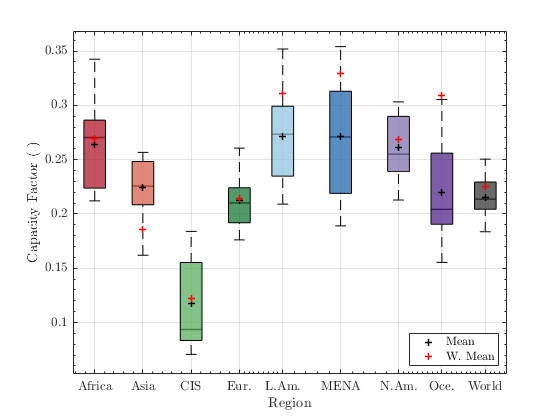


X=categorical(legWB);

figure('Name','Box Win')
hold on
plot(x,Mean_CF_Win,'+k','LineWidth',1.5)
plot(x,Mean_CF_W_Win,'+r','LineWidth',1.5)
b=boxplot(Mat_CF_Win,'position',x,'symbol','');

h = findobj(gca,'Tag','Box');
for j=1:length(h) 
patch(get(h(j),'XData'),get(h(j),'YData'),ColorB(j,:),'FaceAlpha',.75);
end 
lines = findobj(gcf, 'type', 'line', 'Tag', 'Median');
set(lines, 'Color', 'k','LineWidth',1.5);
O = findobj(gcf,'tag','Outliers');
set(O,'MarkerSize',8,'LineWidth',1.5)
plot(x,Mean_CF_Win,'+k','LineWidth',1.5)
plot(x,Mean_CF_W_Win,'+r','LineWidth',1.5)
xlabel('$$\mathrm{Region}$$','interpreter','latex')
ylabel('$$\mathrm{Capacity~Factor~(~)}$$','interpreter','latex')
legend({'Mean','W.~Mean'},'Location','southeast','FontSize', 12,'NumColumns',1,...
    'box','on','interpreter','latex')
set(gca, 'XTickLabel', X);
box on
grid on
xtickangle(0)
set(gca,'XMinorTick','on','YMinorTick','on')
 set(gca,'Fontsize',13,'TickDir','in','FontWeight','normal','GridAlpha',0.13,...
     'LineWidth',0.2,'TickLength',[0.01 0.01],'TickLabelInterpreter','latex') 
%  print('-dpdf','-r400','Wind_CF_B.pdf');
print('-dpng','-r400','Wind_CF_B.png');

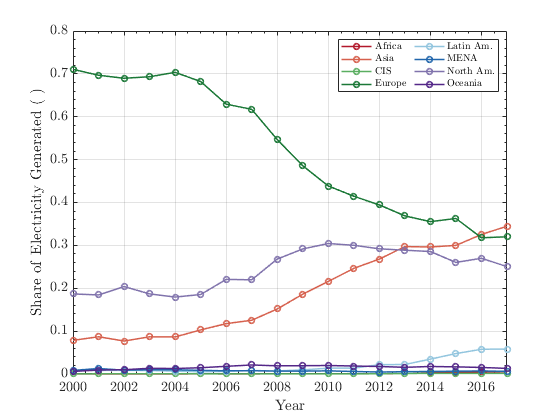

 
 figure('Name','Share Win Electricity')
plot(Year,Africa_El_Win,'-o','Color',Color(1,:),'linewidth',1.5)
hold on
plot(Year,Asia_El_Win,'-o','Color',Color(2,:),'linewidth',1.5)
plot(Year,CIS_El_Win,'-o','Color',Color(3,:),'linewidth',1.5)
plot(Year,Europe_El_Win,'-o','Color',Color(4,:),'linewidth',1.5)
plot(Year,LatAm_El_Win,'-o','Color',Color(5,:),'linewidth',1.5)
plot(Year,MENA_El_Win,'-o','Color',Color(6,:),'linewidth',1.5)
plot(Year,NorAm_El_Win,'-o','Color',Color(7,:),'linewidth',1.5)
plot(Year,Oceania_El_Win,'-o','Color',Color(8,:),'linewidth',1.5)
legend(leg,'Location','northeast','FontSize', 10,'NumColumns',2,...
    'interpreter','latex')
xlabel('$$\mathrm{Year}$$','interpreter','latex')
% ylabel('$$\mathrm{Electricity~from~Wind~(~)}$$','interpreter','latex')
ylabel('$$\mathrm{Share~of~Electricity~Generated~(~)}$$','interpreter','latex')
xlim([2000 2017])
box on
grid on
set(gca,'XMinorTick','on','YMinorTick','on')
set(gca,'Fontsize',14,'TickDir','in','FontWeight','normal','GridAlpha',0.13,...
     'LineWidth',0.2,'TickLength',[0.01 0.01],'TickLabelInterpreter','latex')
% print('-depsc2','-r400','Wind_Share.eps');
print('-dpng','-r400','Wind_Share.png');